# Compound Interest

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

Find and plot the account balance for the first 10 years.

*Remember to define your ODE function at the bottom of this script.*

For a savings account with a 6% annual interest rate, the account balance *A*(*t*) after *t* years solves the differential equation

*d**A/d**t*=*r**A*  where *r*=0.06

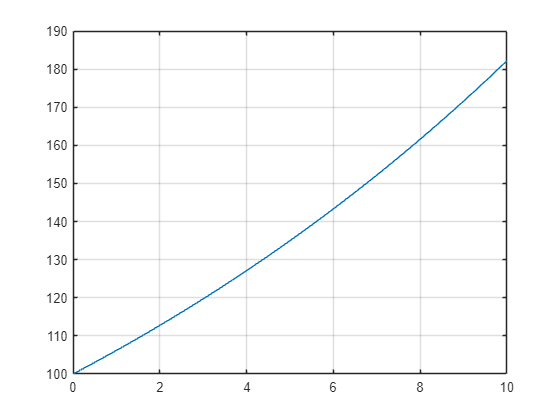

tRange = [0 10];
A0 = 100;
[tSol, ASol] = ode45(@sixPercentInterest, tRange, A0);
plot(tSol, ASol)
grid on

A10 = ASol(end)

A10 = 182.2119

## Task 2

Find the account balance for years 10 through 20, and add it to your previous plot

*Remember to define your ODE function at the bottom of this script.*

Similarly, for an account with a 3% annual interest rate, the account balance *A*(*t*) after *t* years solves the differential equation

*d**A/d**t*=*r**A* where *r*=0.03

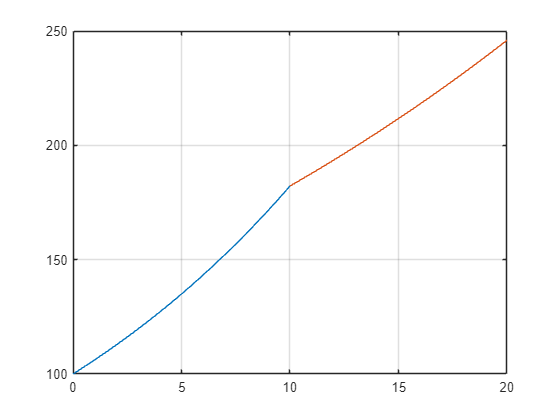

tRange2 = [10 20];
[tSol2, ASol2] = ode45(@threePercentInterest, tRange2, A10);
hold on
plot(tSol2, ASol2)
grid on
hold off

## Task 1 (continued)

Define the ODE function for 6% interest:      where  

function dAdt = sixPercentInterest(t, A)
    dAdt = 0.06*A;
end

## Task 2 (continued)

Define the ODE function for 3% interest:      where  

function dAdt = threePercentInterest(t, A)
    dAdt = 0.03*A;
end